In the name of allah

# Linear Control Systems

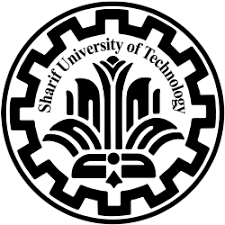

Hw 05

ali sadeghian 400101464

Fall 1402

# Theory Assignments

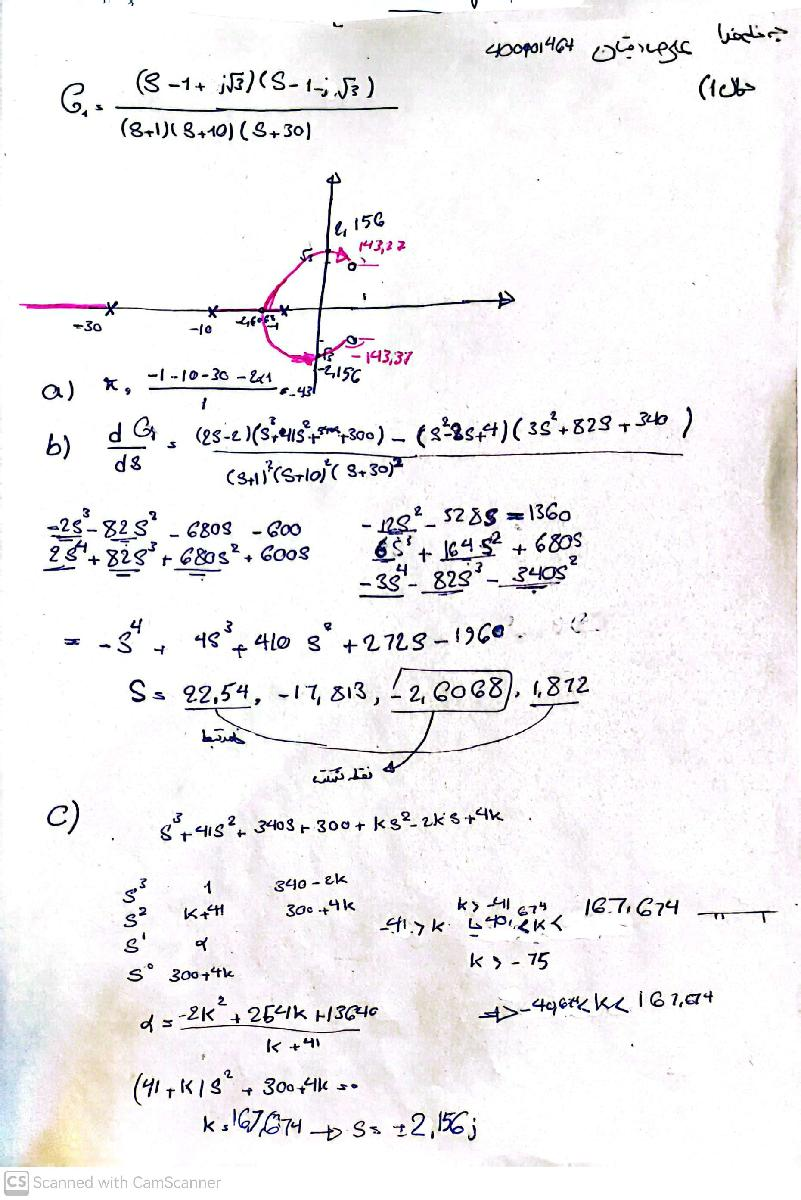

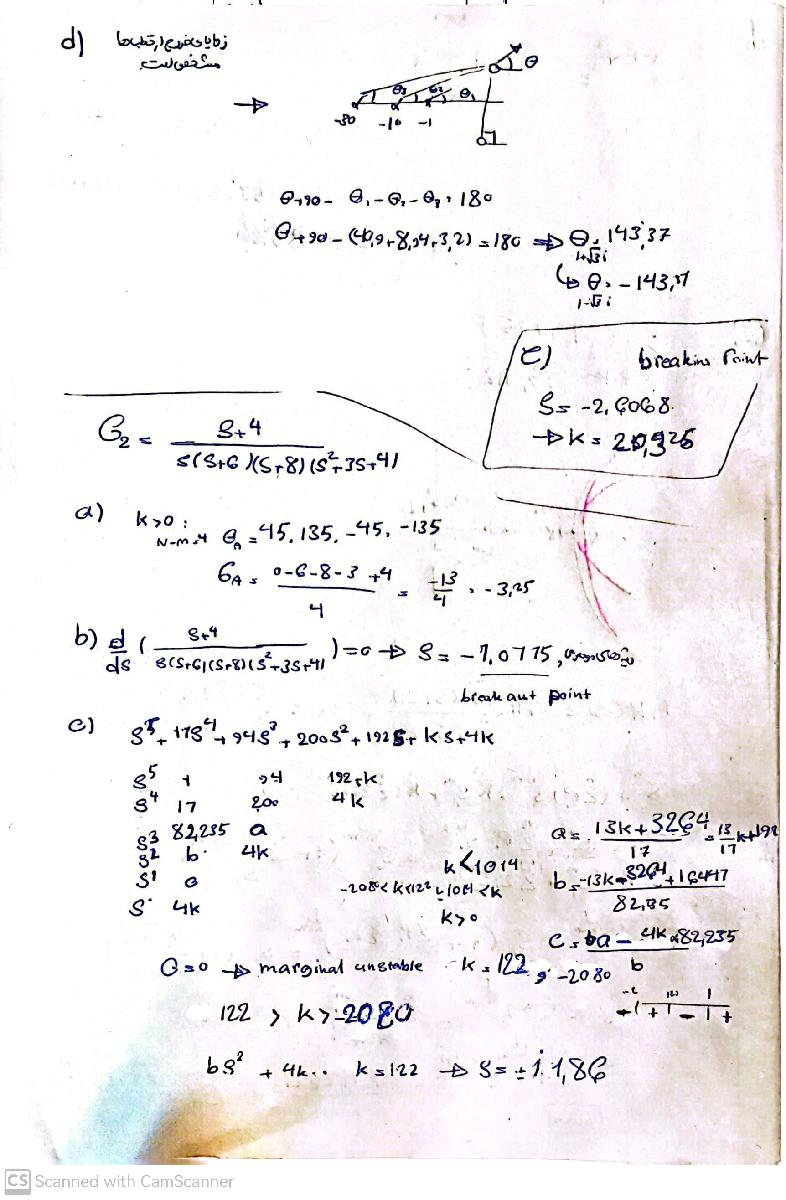

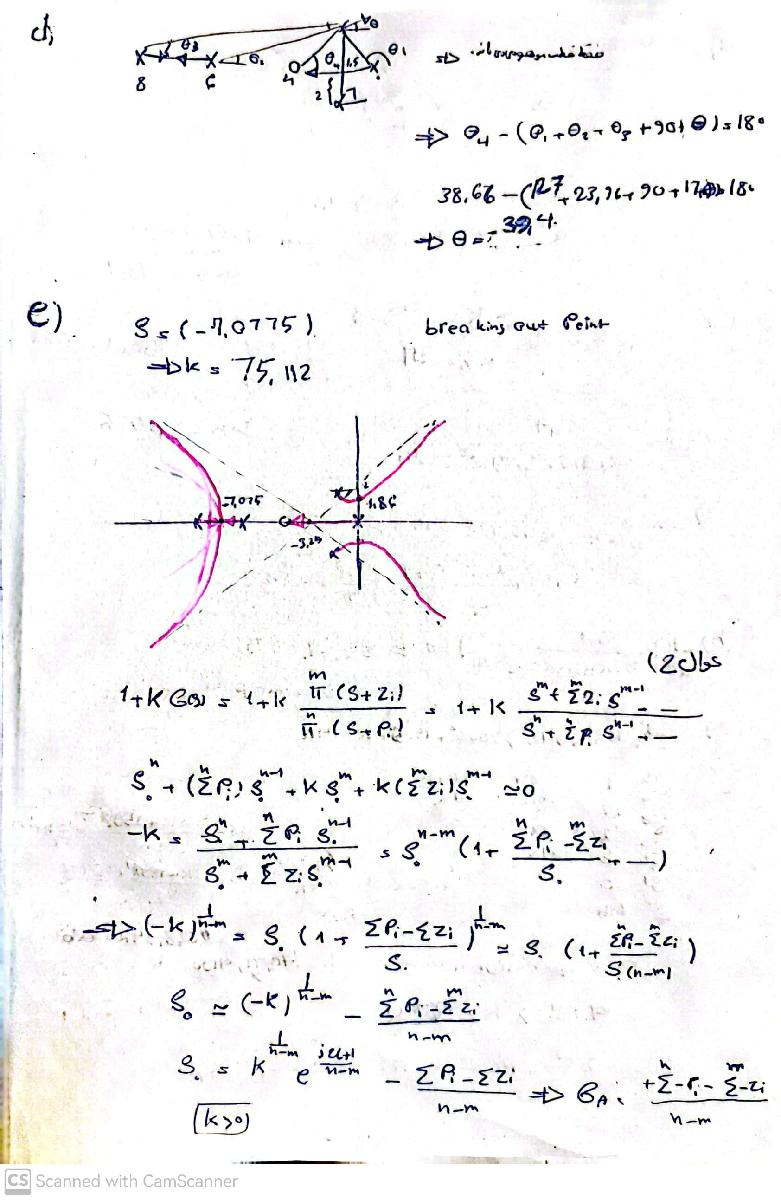

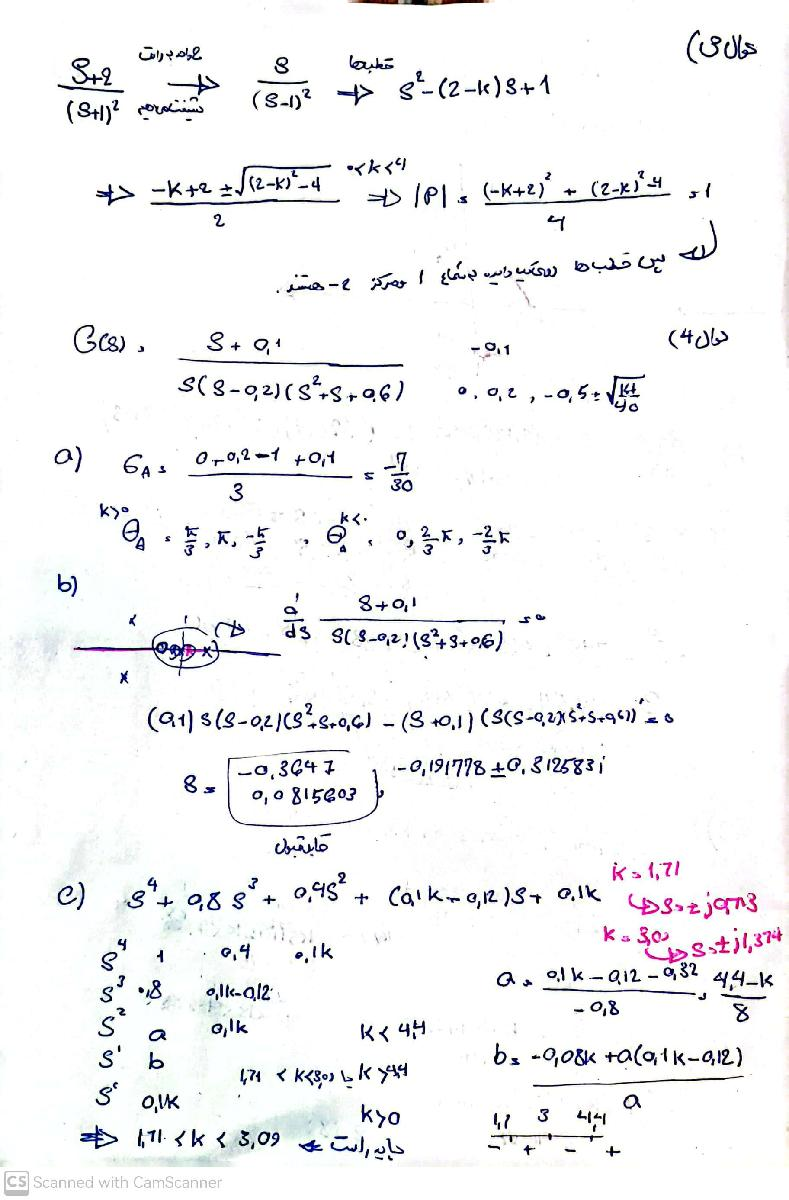

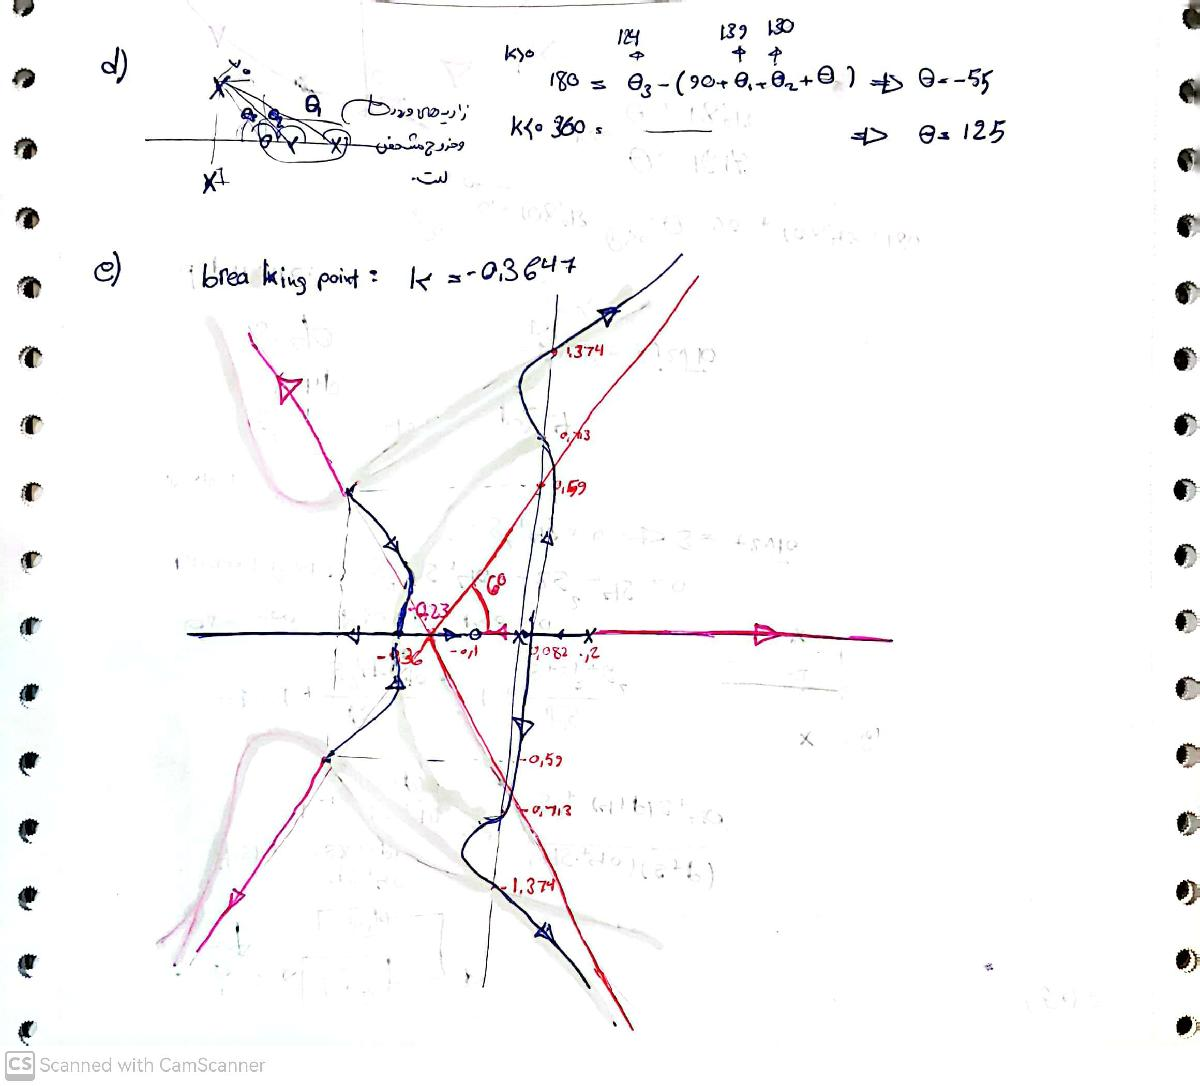

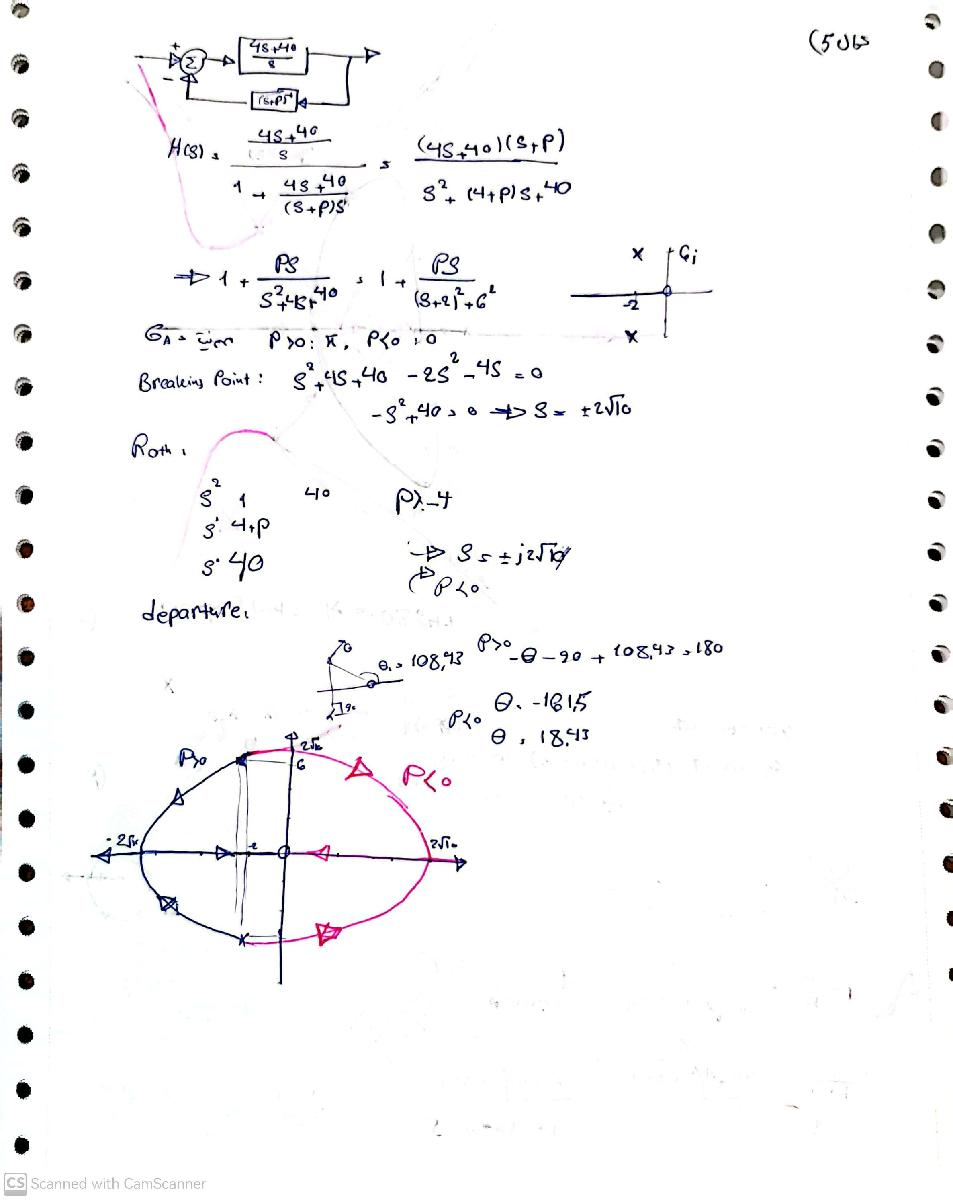

سوال 6

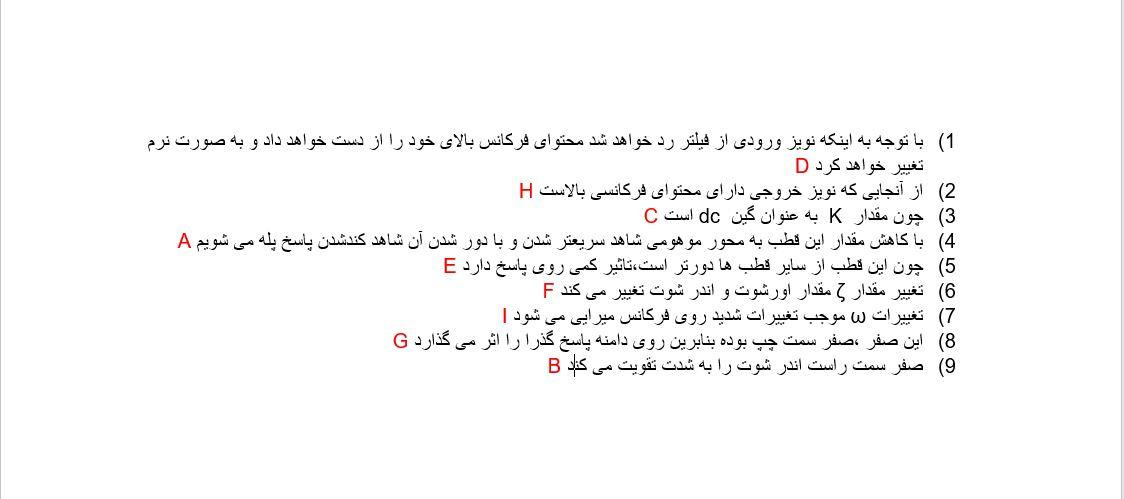

clc
close all
clear all

# MATLAB Assignments

7 Breakaway Points

part a)

syms  s
G1(s) =  (s^2+2*s+2)/(s*(s^2+0.25))

$$G1(s) = \frac{s^{2}+2\,s+2}{s\,\left(s^{2}+\frac{1}{4}\right)}$$

anser = partA(G1,s)

 
anser =
 
Empty sym: 0-by-1
 


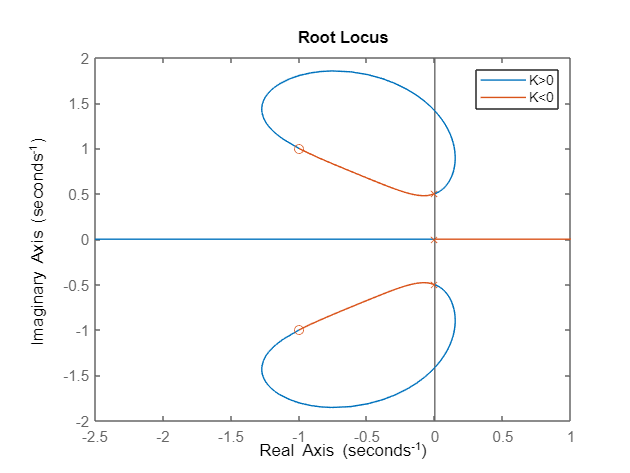


sys1 = tf([1 2 2],[1 0 0.25 0]);
sys2 = -sys1;
rlocus(sys1,sys2)
legend("K>0","K<0")


G2(s) = (s^2 / (s^2-1)^2)

$$G2(s) = \frac{s^{2}}{{\left(s^{2}-1\right)}^{2}}$$

anser = partA(G2,s)

$$anser = \left(\begin{array}{c} 0\\ -1.0\,\mathrm{i}\\ 1.0\,\mathrm{i} \end{array}\right)$$

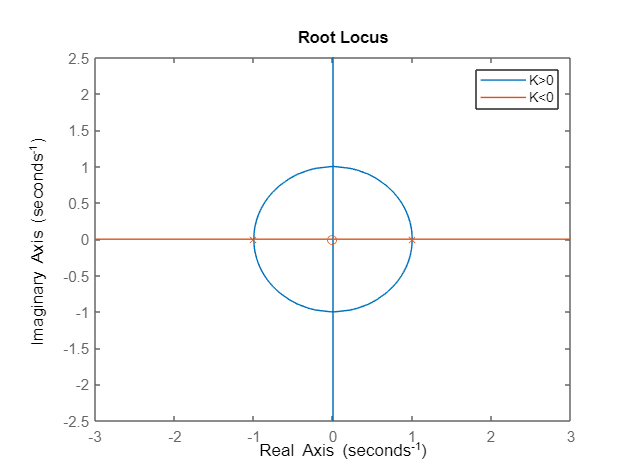


sys1 = tf([1 0 0],[1 0 -2 0 1]);
sys2 = -sys1;
rlocus(sys1,sys2)
legend("K>0","K<0")

part (b)

We can plot complementary root locus with By multiplying -1 in the transfer function

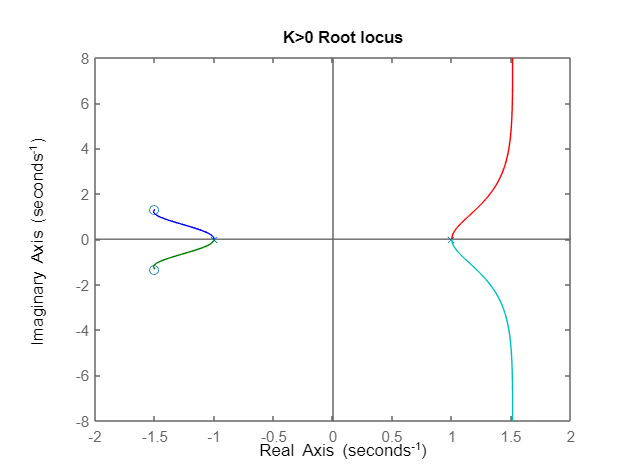

sys1 = tf([1 3 4],[1 0 -2 0 1]);
sys2 = -sys1;
rlocus(sys1)
title("K>0 Root locus")

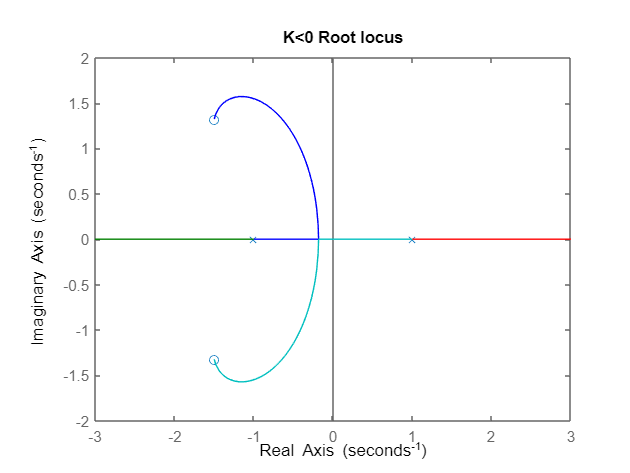

rlocus(sys2)
title("K<0 Root locus")

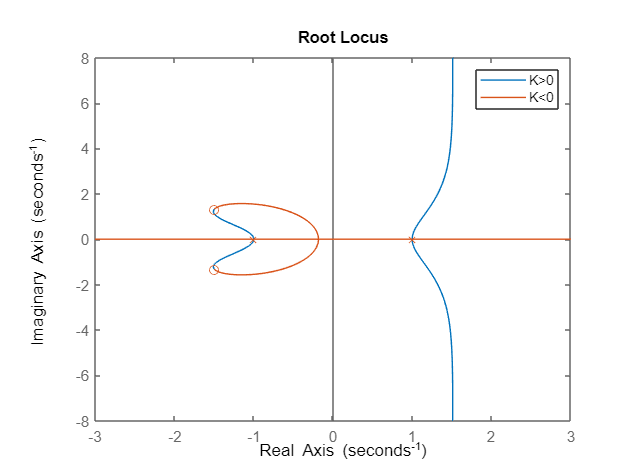

rlocus(sys1,sys2)
legend("K>0","K<0")

part (c)

G1(s) =  (s^2+2*s+2)/(s*(s^2+0.25))

$$G1(s) = \frac{s^{2}+2\,s+2}{s\,\left(s^{2}+\frac{1}{4}\right)}$$

[R,complementaryR,non] = partC(G1,s)

 
R =
 
Empty sym: 0-by-1
 
 
complementaryR =
 
Empty sym: 0-by-1
 


$$non = \left(\begin{array}{c} -2.0291289456597803634180201034811-1.3357918919869738626969712269717\,\mathrm{i}\\ -2.0291289456597803634180201034811+1.3357918919869738626969712269717\,\mathrm{i}\\ 0.029128945659780363418020103481059-0.28960800211921472630369875126637\,\mathrm{i}\\ 0.029128945659780363418020103481059+0.28960800211921472630369875126637\,\mathrm{i} \end{array}\right)$$

sys1 = tf([1 2 2],[1 0 0.25 0]);
sys2 = -sys1;
rlocus(sys1,sys2)
legend("K>0","K<0")


G2(s) = (s^2 / (s^2-1)^2)

$$G2(s) = \frac{s^{2}}{{\left(s^{2}-1\right)}^{2}}$$

[R,complementaryR,non] = partC(G2,s)

$$R = \left(\begin{array}{c} -1.0\,\mathrm{i}\\ 1.0\,\mathrm{i} \end{array}\right)$$

 
complementaryR =
 
Empty sym: 0-by-1
 
 
non =
 
Empty sym: 0-by-1
 



sys1 = tf([1 0 0],[1 0 -2 0 1]);
sys2 = -sys1;
rlocus(sys1,sys2)
legend("K>0","K<0")

function G = partA(Gi , s)
Gip(s) = diff(Gi , s);          % finding diff
s1 = vpasolve(Gip == 0, s);     % finding valid s
GG = Gi(s1);                    % value of G(s)
idg = imag(GG) == 0;            % find real G(s0)
G = s1(idg);                    % delete complex G(s0)
end

function [G,Gc,N] = partC(Gi , s)
Gip(s) = diff(Gi , s);          % finding diff
s1 = vpasolve(Gip == 0, s);     % finding valid s
GG = Gi(s1);                    % value of G(s)
idg = (imag(GG) == 0);          % find real G(s0)
N = s1(~idg);                   % delete all real values G(s0)
idgc = imag(GG) == 0 & real(GG) > 0;  % find real G(s0)>0 :K<0  
idga = imag(GG) == 0 & real(GG) < 0;  % find real G(s0)<0 :K>0 
G = s1(idga);                   % add just K>0
Gc = s1(idgc);                  % add just K<0

end